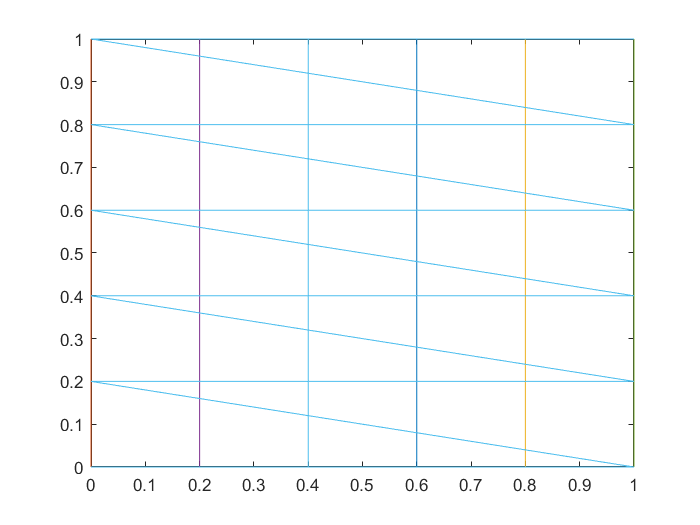

% a=[1 2 2 1];
% b=[1 1 3 3];
% c=[2 3 4];
% d=[1 2 1];
clear
close all
clc
d1=1;
d2=1;
p=5;
m=5;
[NL,EL]=uniform_mesh(d1,d2,p,m);
for ii=1:6
    f=(ii-1)*6+(1:6);
    g=ii:6:36;
    plot(NL(f,1),NL(f,2))
    hold on
    plot(NL(g,1),NL(g,2))
%     hold off
end
plot(NL(:,1),NL(:,2))
hold off


Noe= p*m;
Non= (p+1)*(m+1);
for i=1:p
    for j=1:m

         l=EL(((j-1)*p)+i,:);
         x=NL(l,1);
         y=NL(l,2);
         z=[x y];
    b1=z(2,:)-z(1,:);
    b2=z(3,:)-z(2,:);
    b3=z(4,:)-z(3,:);
    b4=z(1,:)-z(4,:);
    B=[b1;b2;b3;b4];
    B=repmat(B,4,1);
    k=[0.1 0.5;2 4;5 6;0.5 1];
%     ;2 4;5 6;0.5 1
    a1=k(1,:)-z;
    a2=k(2,:)-z;
    a3=k(3)-z;
    a4=k(4,:)-z;
    A=[a1;a2;a3;a4];
    BA=B.*A;
%     s=BA(BA~=0);
    s=BA*ones(2,1); % extract nonzeros row wise
% s=nonzeros(BA);
    h=all(s>0);
    end
   
end
%     z=[x y];
%     b1=z(2,:)-z(1,:);
%     b2=z(3,:)-z(2,:);
%     b3=z(4,:)-z(3,:);
%     b4=z(1,:)-z(4,:);
%     B=[b1;b2;b3;b4];
%     pol= polyshape({x},{y});
%   plot(pol)
%     X=0.2;
%     Y=0;
%     
%     end
% end

% plot(pol)
% hold on
% x=[1 2.5 3];
% y=[0.25 0 1.5];
% x=isinterior(pol,x,y)